Cau 1:

clear;clc
bitstream = [ 0 1 0 0 1 1 0 0 0 1 0];
pulse_high = 5;
pulse_low = 0;
for bit = 1:length(bitstream)
    % set bit time
    bt = bit-1:0.001:bit;
    if bitstream(bit) == 0
        % low level pulse
        y = (bt<bit)*pulse_low;

    else
        % high level pulse
        y = (bt<bit) * pulse_high;
    end
    
    try
        if bitstream(bit+1) == 1
            y(end) = pulse_high;
        end
    catch e
        % assume next bit is 1
        y(end) = pulse_high;
    end
    
    % draw pulse and label
    plot(bt, y, 'LineWidth', 2);
    text(bit-0.5,pulse_high+0.5, num2str(bitstream(bit)), 'FontWeight', 'bold');
    hold on;
end

% draw grid
 grid on;
 axis([0 length(bitstream) pulse_low-1 pulse_high+1]);
 set(gca,'YTick', [pulse_low pulse_high])
 set(gca,'XTick', 1:length(bitstream))
 title('Unipolar Non-Return-to-Zero Level')

Cau 2:

 clear;clc
bitstream = [ 0 0 0 0 0 0 0 0 0 0 0];
pulse_high = 5;
pulse_low = 0;
for bit = 1:length(bitstream)
    % set bit time
    bt = bit-1:0.001:bit;
    if bitstream(bit) == 0
        % low level pulse
        y = (bt<bit)*pulse_low;

    else
        % high level pulse
        y = (bt<bit) * pulse_high;
    end
    
    try
        if bitstream(bit+1) == 1
            y(end) = pulse_high;
        end
    catch e
        % assume next bit is 1
        y(end) = pulse_high;
    end
    
    % draw pulse and label
    plot(bt, y, 'LineWidth', 2);
    text(bit-0.5,pulse_high+0.5, num2str(bitstream(bit)), 'FontWeight', 'bold');
    hold on;
end

% draw grid
 grid on;
 axis([0 length(bitstream) pulse_low-1 pulse_high+1]);
 set(gca,'YTick', [pulse_low pulse_high])
 set(gca,'XTick', 1:length(bitstream))
 title('Unipolar Non-Return-to-Zero Level')

Cau 3:

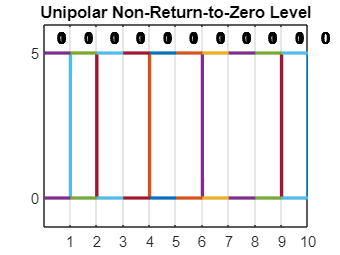

 clear;clc
bitstream = [ 1 1 1 1 1 1 1 1 1 1];
pulse_high = 5;
pulse_low = 0;
for bit = 1:length(bitstream)
    % set bit time
    bt = bit-1:0.001:bit;
    if bitstream(bit) == 0
        % low level pulse
        y = (bt<bit)*pulse_low;

    else
        % high level pulse
        y = (bt<bit) * pulse_high;
    end
    
    try
        if bitstream(bit+1) == 1
            y(end) = pulse_high;
        end
    catch e
        % assume next bit is 1
        y(end) = pulse_high;
    end
    
    % draw pulse and label
    plot(bt, y, 'LineWidth', 2);
    text(bit-0.5,pulse_high+0.5, num2str(bitstream(bit)), 'FontWeight', 'bold');
    hold on;
end

% draw grid
 grid on;
 axis([0 length(bitstream) pulse_low-1 pulse_high+1]);
 set(gca,'YTick', [pulse_low pulse_high])
 set(gca,'XTick', 1:length(bitstream))
 title('Unipolar Non-Return-to-Zero Level')